Suite TP2 (thème3)  de TNS2

clear all

sigmab = sqrt(10)

sigmab = 3.1623

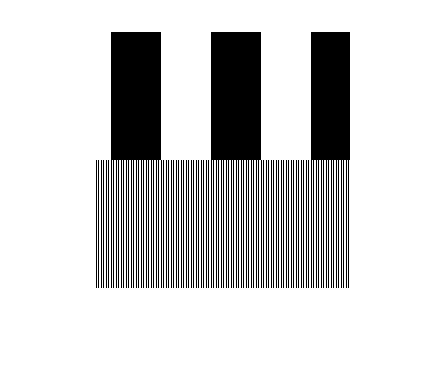

vectN = 0:255;
nu1 = 0.01; nu2 = 0.4;
Vh = cos(2*pi*nu1*vectN+pi/6);
Vv = cos(2*pi*nu2*vectN-3*pi/8);
ima1 = [ones(128,1)*Vh; ones(128,1)*Vv]*255;
ima2 = ima1.';
ima3 = ima1.*ima2;
imshow(ima1)

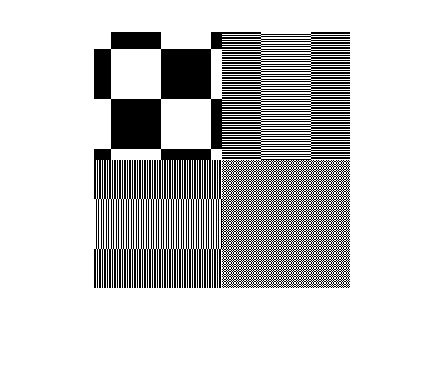

figure()
imshow(ima3)

Création du bruit

Bruit2D = genBruit2D(128, sigmab)

Bruit2D =    12.6145   -1.6729   12.3607  -10.3410    5.2750    4.5543    6.4049   -3.0585  -26.1729    0.1628   -2.9506   19.8086   -4.0094   -2.0969  -16.4972    8.6363   10.5947   14.0019   -7.4055  -11.7448    0.5627   -0.7097   10.5047    0.1654    4.1604   -0.1093  -14.2495    2.3891    5.2397   -5.7619    5.5043   -0.9931   -6.6700    8.7983   -0.4011    3.7965  -11.0699   20.2215  -12.8020    5.5258  -12.4630    2.3484    3.3108   24.0156    5.5615   -9.6522   -0.5901   -4.4541    4.2565    1.5724
    8.0340   -9.4309   -3.9221   -6.7935   -8.5715    3.2886   -1.3106  -15.3596   -7.9236    4.3624    3.2744   -8.7389   -4.4067   -1.9542   -1.9678   -9.8589   -2.6342   18.2279   -1.0409    5.8718   13.5087    9.8912   -5.2303    9.4447  -13.1525    3.5114  -15.8517    5.3311    2.7425   15.5177    9.3301    2.9650   -2.4504    6.5200    7.8557   16.7064   -1.5973   -1.7848    5.6327  -20.5067   -5.5889   -6.9196   14.6860   11.7137   -2.5407   -0.4391    4.0370   12.1897    9.219

[I2dBruit2D] = spectrogramme2D(Bruit2D)

I2dBruit2D =     4.2236   62.0353  196.5860  195.2174  250.6445   78.2854    6.5757  347.0241   17.5450   18.5458   14.2242   21.8381    3.0874  277.2296   40.7382  224.0778   45.0182   53.2312  288.4289  197.9861   84.0760  115.3975   34.8862    2.7441  252.5295   45.9820  202.4304   83.4676   21.3859    0.2515   81.8842   50.9770   91.9123  203.0327  187.2309   46.7178   99.4969   49.7793  235.8122   69.2883  125.1899   98.1458    5.4168   88.2728   16.8516  119.3859   68.0265   66.3413   15.9786   95.2286
    7.7234   73.4789  107.2462   26.3851    1.0514   33.0040   90.1298  123.0335  140.8167   77.3123  207.4506  353.3389  249.6452    4.4611   31.2667  158.7145    9.9786  193.5835   61.1219    7.3694    7.2099   38.7092   79.0267  150.7119  452.2017    1.9917  241.2669   66.6561   95.2046   89.5357  326.5237   27.9269  154.9957  117.1537   82.8661  153.0565  169.1709   17.9588  131.3250  130.1215   34.3341   20.8430  145.9097   67.6023    6.2057   12.4219   11.1552   45.7253   21.

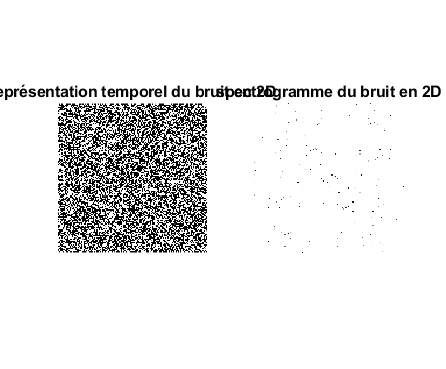


subplot(121)
imshow(Bruit2D)
title("représentation temporel du bruit en 2D")


subplot(122)
imshow(I2dBruit2D)
title("spectrogramme du bruit en 2D")

Observations des Puissances / RSB

sigmab2 = sigmab^2

sigmab2 = 10.0000


Pb = Puissance2D(Bruit2D)

Pb = 100.1161

Pim1 = Puissance2D(ima1)

Pim1 = 3.2545e+04

Pim3 = Puissance2D(ima3)

Pim3 = 1.0618e+09


RSBdB1 = 10*log10(Pim1/Pb) 

RSBdB1 = 25.1198

RSBdB3 = 10*log10(Pim3/Pb) 

RSBdB3 = 70.2554

Hmoy = 1/9*[1 1 1; 1 1 1; 1 1 1]

Hmoy =     0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111



ybruit = conv2(Hmoy, Bruit2D);

ybruit =     1.4016    1.2157    2.5891    0.0385    0.8105   -0.0569    1.8038    0.8779   -2.5363   -3.2299   -3.2179    1.8912    1.4276    1.5225   -2.5115   -1.1064    0.3037    3.6925    1.9101   -0.5720   -2.0653   -1.3213    1.1508    1.1067    1.6478    0.4685   -1.1332   -1.3300   -0.7356    0.2074    0.5536   -0.1390   -0.2399    0.1261    0.1919    1.3549   -0.8527    1.4387   -0.4056    1.4384   -2.1933   -0.5099   -0.7560    3.2972    3.6542    2.2139   -0.5201   -1.6329   -0.0875    0.1528
    2.2943    1.0605    1.9981   -2.2000   -1.3325   -1.3987    1.0712   -0.6090   -5.2689   -5.3322   -3.2497    1.7687    0.3308   -0.1553   -3.4369   -2.6376   -1.3030    4.3297    3.5271    1.9900   -0.0276    1.9311    3.1697    2.6740    0.6547    0.4467   -3.9657   -2.1088   -1.5999    2.8287    3.6192    2.9513    0.8540    0.9078    1.5169    4.8084    1.6989    2.9191   -0.1555   -0.4126   -4.4669   -4.1782   -0.5140    5.4617    6.3052    3.1843   -0.4026    0.1212    2.7399

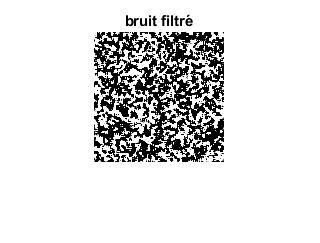


figure() 


imshow(ybruit)
title("bruit filtré")

yutile1 = conv2(Hmoy, ima1);

yutile1 =    24.5374   48.1368   70.7052   67.6160   64.2599   60.6503   56.8013   52.7281   48.4468   43.9744   39.3284   34.5271   29.5896   24.5354   19.3843   14.1567    8.8732    3.5547   -1.7778   -7.1033  -12.4007  -17.6492  -22.8281  -27.9169  -32.8955  -37.7443  -42.4441  -46.9764  -51.3233  -55.4677  -59.3931  -63.0842  -66.5263  -69.7059  -72.6103  -75.2282  -77.5492  -79.5642  -81.2651  -82.6453  -83.6994  -84.4232  -84.8137  -84.8696  -84.5905  -83.9775  -83.0332  -81.7611  -80.1664  -78.2553
   49.0748   96.2736  141.4103  135.2320  128.5199  121.3006  113.6026  105.4562   96.8937   87.9487   78.6567   69.0543   59.1793   49.0708   38.7686   28.3134   17.7465    7.1095   -3.5555  -14.2065  -24.8014  -35.2985  -45.6562  -55.8338  -65.7910  -75.4885  -84.8882  -93.9528 -102.6466 -110.9354 -118.7863 -126.1684 -133.0526 -139.4117 -145.2206 -150.4564 -155.0984 -159.1283 -162.5302 -165.2907 -167.3988 -168.8463 -169.6274 -169.7391 -169.1809 -167.9551 -166.0663 -163.5222 -160.332

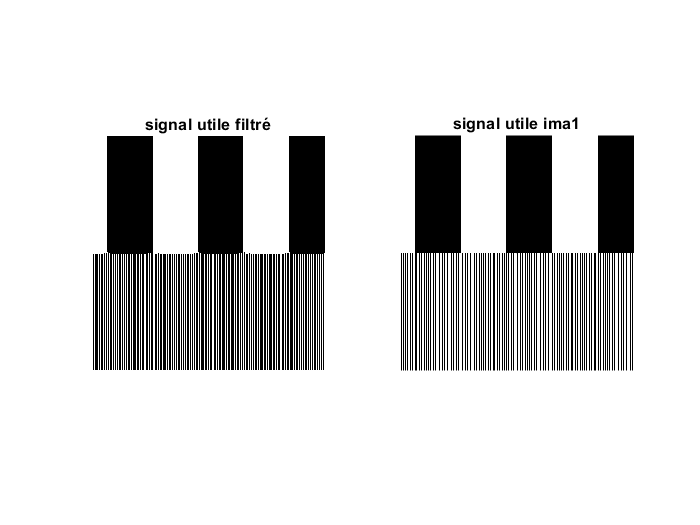


figure() 

subplot(121)
imshow(yutile1)
title("signal utile filtré")
subplot(122)

imshow(ima1)
title("signal utile ima1")



%ytotal1 = conv2(Hmoy, Bruit2D+ima1)
%imshow(ytotal1)
%title("signal total filtré")